clear all
clc

% sympref('AbbreviateOutput',false);

% Robot dimensions and other parameters
a_1 = 0.050;  a_2 = 0.093;  a_3 = 0.093;  a_4 = 0.050; % Robot dimensions [m]
m_1 = 0.060;  m_2 = 0.080;  m_3 = 0.080;  m_4 = 0.040; % Link masses [kg]
m_1_disk = 0.010;    m_1_link = m_1-m_1_disk; % Masses of subcomponents of link 1 [kg]
a = 0.032; b = 0.040; R = 0.055; % Measures of link 1 base and ratio of its disk [m]
% Distance from center of mass following the assignment [m]
d1 = -0.020;  d2 = -0.030;  d3 = -0.030;  d4 = -0.025;  d5 = 0.015; 

syms x y z
syms theta_1      theta_2      theta_3      theta_4
syms theta_dot_1  theta_dot_2  theta_dot_3  theta_dot_4
syms theta_ddot_1 theta_ddot_2 theta_ddot_3 theta_ddot_4
zeros = [0 0 0]';  % to be used in the Jacobians

% Defining velocities and accelerations vectors
q = [theta_1 theta_2 theta_3 theta_4].';
q_dot = [theta_dot_1 theta_dot_2 theta_dot_3 theta_dot_4].';
q_ddot = [theta_ddot_1 theta_ddot_2 theta_ddot_3 theta_ddot_4].';

We need to find tau as:

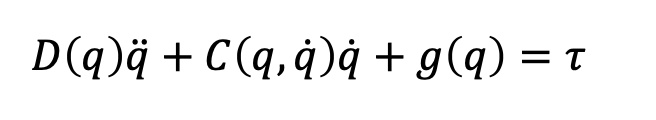

Let's begin by finding D, for which we need the Jacobians at the centers of mass;

% Creating DH parameters - pi/2 ???
DH_parameters = [theta_1    a_1   0      pi/2
                 theta_2    0     a_2    0
                 theta_3    0     a_3    0
                 theta_4    0     a_4    0];

% Extracting single rotation matrices for each set of axes
T_01 = DH(DH_parameters(1,:));
T_02 = DH(DH_parameters(1:2,:));
T_03 = DH(DH_parameters(1:3,:));
T_04 = DH(DH_parameters(1:4,:));

% Finding the matrices for the centers of mass instead, translating
T_0cm1 = T_01*translation(y,d1);
T_0cm2 = T_02*translation(x,d2);
T_0cm3 = T_03*translation(x,d3);
T_0cm4 = T_04*translation(x,d4)*translation(y,d5);

% Extract values of axis origin, CM, and z axis orientation from rotation matrix
o_0 = [0 0 0].';           z_0 = [0 0 1].';
o_1 = T_01(1:3,4);         z_1 = T_01(1:3,3);
o_2 = T_02(1:3,4);         z_2 = T_02(1:3,3);
o_3 = T_03(1:3,4);         z_3 = T_03(1:3,3);
o_4 = T_04(1:3,4);         z_4 = T_04(1:3,3);
o_cm1 = vpa(T_0cm1(1:3,4),3);
o_cm2 = vpa(T_0cm2(1:3,4),3);
o_cm3 = vpa(T_0cm3(1:3,4),3);
o_cm4 = vpa(T_0cm4(1:3,4),3);
% Creating J matrices for each center of mass
J_cm4 = [cross(z_0,(o_cm4-o_0))  cross(z_1,(o_cm4-o_1))  cross(z_2,(o_cm4-o_2))  cross(z_3,(o_cm4-o_3))
                   z_0                     z_1                     z_2                     z_3         ];
J_cm3 = [cross(z_0,(o_cm3-o_0))  cross(z_1,(o_cm3-o_1))  cross(z_2,(o_cm3-o_2))           zeros
                   z_0                     z_1                     z_2                    zeros];
J_cm2 = [cross(z_0,(o_cm2-o_0))  cross(z_1,(o_cm2-o_1))           zeros                   zeros
                   z_0                     z_1                    zeros                   zeros];
J_cm1 = [cross(z_0,(o_cm1-o_0))           zeros                   zeros                   zeros
                   z_0                    zeros                   zeros                   zeros];

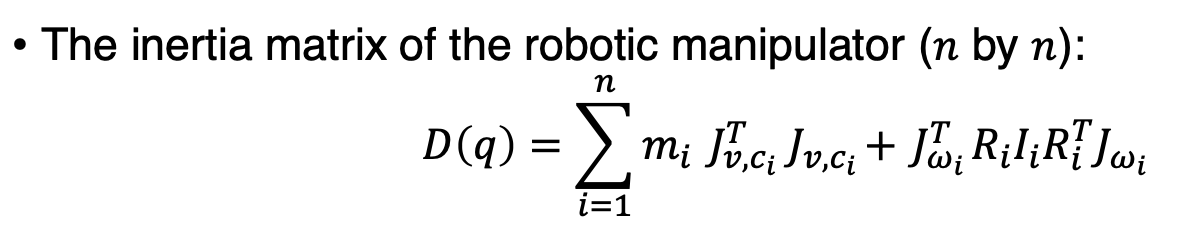

% Divide the Jacobians in the ones for linear and angular velocity
J_v_cm1 = J_cm1(1:3,:);     J_w_cm1 = J_cm1(4:6,:);
J_v_cm2 = J_cm2(1:3,:);     J_w_cm2 = J_cm2(4:6,:);
J_v_cm3 = J_cm3(1:3,:);     J_w_cm3 = J_cm3(4:6,:);
J_v_cm4 = J_cm4(1:3,:);     J_w_cm4 = J_cm4(4:6,:);

Where the following are:

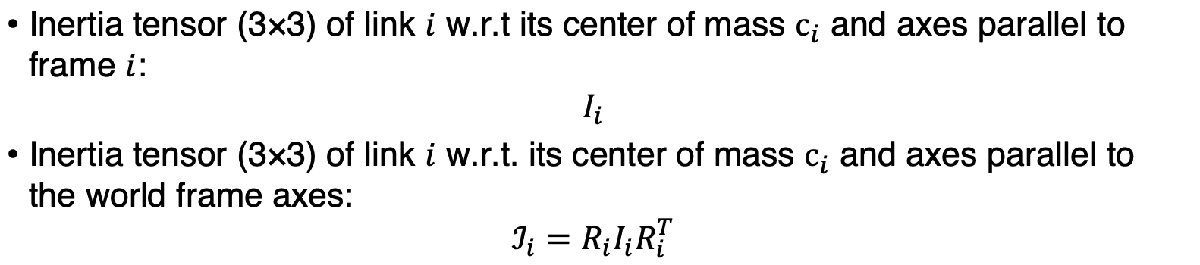

To find I_0 we use the matrix D_bar_1, for the first link, where the moment of inertia around y, I_yy, is given as 0.4*I_0. Calculating I_yy we can easily find I_0, which is then going to be the same everywhere

I_link = 1/12 * m_1_link * (a^2+b^2); % Inertia of a parallelepiped, a and b are
% the two sides of the link base (we are not interested in height)
I_disk = 1/2 * m_1_disk * R^2; % Inertia of a disk of ratio R wrt Y axis
syms I_0
I_0 = solve(I_link + I_disk == 0.4*I_0, I_0);

% Built Inertia tensor wrt CM (center of mass) -> Given in the assignment,
% but called D_bar_1 [...]
I_1 = [I_0     0       0
       0   0.4*I_0     0
       0       0    0.9*I_0];
I_2 = [0.45*I_0    0       0
          0     1.4*I_0    0
          0        0    1.2*I_0];   I_3 = I_2;
I_4 = [0.5*I_0    0       0
          0    0.5*I_0    0
          0       0    0.5*I_0];

% Find inertia tensors wrt global axis (ONLY ROTATIONS, NO TRANSLATIONS!)
R_1 = T_0cm1(1:3,1:3);
J_1 = R_1 * I_1 * transpose(R_1);
R_2 = T_0cm2(1:3,1:3);
J_2 = R_2 * I_2 * transpose(R_2);
R_3 = T_0cm3(1:3,1:3);
J_3 = R_3 * I_3 * transpose(R_3);
R_4 = T_0cm4(1:3,1:3);
J_4 = R_4 * I_4 * transpose(R_4);

% Finally compute D
D = m_1*transpose(J_v_cm1)*J_v_cm1 + transpose(J_w_cm1)*J_1*J_w_cm1 + ...
    m_2*transpose(J_v_cm2)*J_v_cm2 + transpose(J_w_cm2)*J_2*J_w_cm2 + ...
    m_3*transpose(J_v_cm3)*J_v_cm3 + transpose(J_w_cm3)*J_3*J_w_cm3 + ...
    m_4*transpose(J_v_cm4)*J_v_cm4 + transpose(J_w_cm4)*J_4*J_w_cm4;

g_vector = [0; 0; -9.81]; % NOTE: gravity is wrt global axes, therefore not necessarly z, and negative.

% Rename the location of CM to respect the notation in the slides
r_cm1 = o_cm1;       r_cm2 = o_cm2;      r_cm3 = o_cm3;     r_cm4 = o_cm4; 

% Compute potential energy P
P = - (m_1*transpose(g_vector)*r_cm1 + m_2*transpose(g_vector)*r_cm2 + ...
       m_3*transpose(g_vector)*r_cm3 + m_4*transpose(g_vector)*r_cm4);
P = simplify(P);

% Find g(q)
g = [diff(P,q(1))
     diff(P,q(2))
     diff(P,q(3))
     diff(P,q(4))];
g = simplify(g)

$$g = \left(\begin{array}{c} 0\\ 0.085935600000376871321350336074829\,\cos\left(\theta_{2}+\theta_{3}\right)-0.011440327617737280002705162050207\,\sin\left(\theta_{2}+\theta_{3}+\theta_{4}-1.0303768265229749715792596657808\right)+0.15892200000097072916105389595032\,\cos\left(\theta_{2}\right)\\ 0.085935600000376871321350336074829\,\cos\left(\theta_{2}+\theta_{3}\right)-0.011440327617737280002705162050207\,\sin\left(\theta_{2}+\theta_{3}+\theta_{4}-1.0303768265229749715792596657808\right)\\ -0.011440327617737280002705162050207\,\sin\left(\theta_{2}+\theta_{3}+\theta_{4}-1.0303768265229749715792596657808\right) \end{array}\right)$$


% Calculate Christoffel parameters and C matrix (see functions)
christoffel_parameters = christoffel(D,q);
C = christoffelMatrix(christoffel_parameters,q_dot);

tau = D*q_ddot + C*q_dot + g;

tau_1 = simplify(tau(1));

tau_2 = simplify(tau(2));

tau_3 = simplify(tau(3));

tau_4 = simplify(tau(4));

Now we can calculate the values of postion, velocity and acceleration for each point of the trajctory of problem 6/7, to then substitute the values in the equation for tau, to be plotted

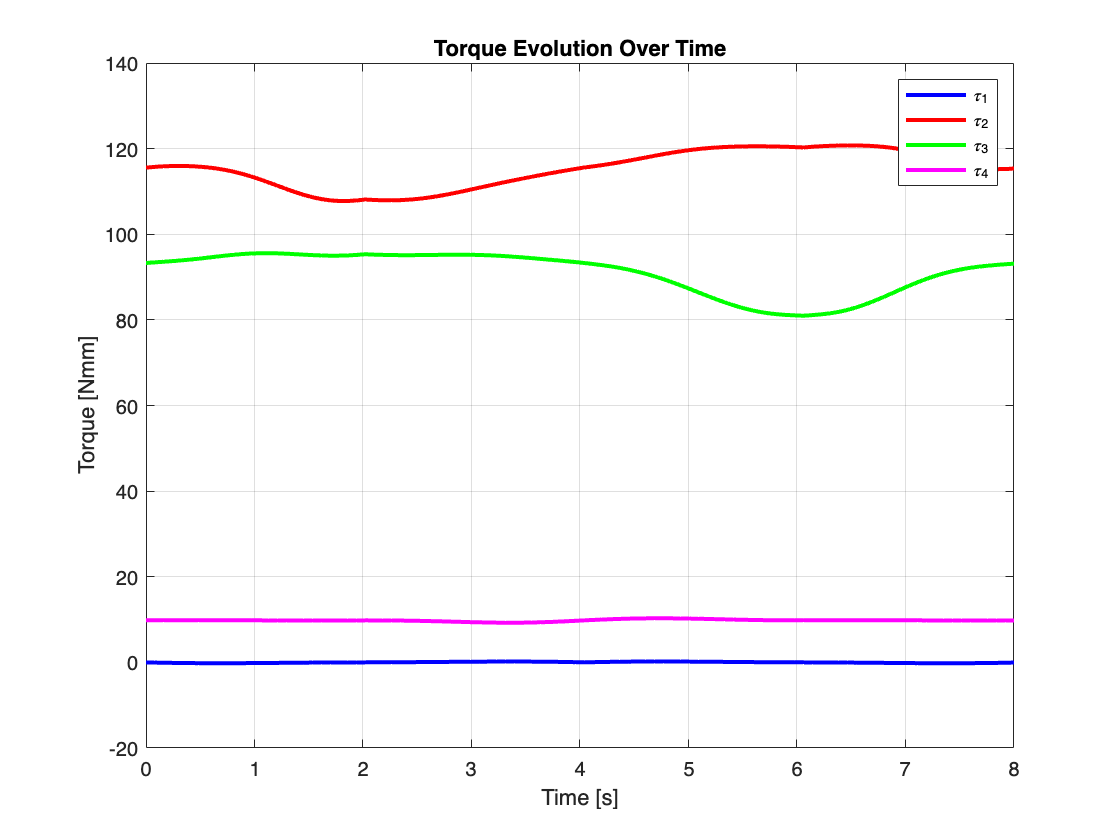

% Let's first import the matrices from the .MAT file, to avoid calculating
% them again in this file
load('ABCD_input');

% Define the desired number of points for the interpolation:
points = 100;

syms t
t_coefficients_syms = [1  t  t^2   t^3     t^4      t^5
                       0  1  2*t   3*t^2   4*t^3    5*t^4
                       0  0  2     6*t     12*t^2   20*t^3];

% Interpolate to find values of position, velocity and acceleration as
% arrays, using the loaded A B C D matrices
q_array = [];
for i=1:4
    if i==1
        q_1_current = A(:,1).'*t_coefficients_syms(1,:).'; q_2_current = A(:,2).'*t_coefficients_syms(1,:).';
        q_3_current = A(:,3).'*t_coefficients_syms(1,:).'; q_4_current = A(:,4).'*t_coefficients_syms(1,:).';
    end
    if i==2
        q_1_current = B(:,1).'*t_coefficients_syms(1,:).'; q_2_current = B(:,2).'*t_coefficients_syms(1,:).';
        q_3_current = B(:,3).'*t_coefficients_syms(1,:).'; q_4_current = B(:,4).'*t_coefficients_syms(1,:).';
    end
    if i==3
        q_1_current = C(:,1).'*t_coefficients_syms(1,:).'; q_2_current = C(:,2).'*t_coefficients_syms(1,:).';
        q_3_current = C(:,3).'*t_coefficients_syms(1,:).'; q_4_current = C(:,4).'*t_coefficients_syms(1,:).';
    end
    if i==4
        q_1_current = D(:,1).'*t_coefficients_syms(1,:).'; q_2_current = D(:,2).'*t_coefficients_syms(1,:).';
        q_3_current = D(:,3).'*t_coefficients_syms(1,:).'; q_4_current = D(:,4).'*t_coefficients_syms(1,:).';
    end
    q_array_current = [q_1_current q_2_current q_3_current q_4_current];
    q_array = [q_array; q_array_current];
end  

q_dot_array = [];
for i=1:4
    if i==1
        q_dot_1_current = A(:,1).'*t_coefficients_syms(2,:).'; q_dot_2_current = A(:,2).'*t_coefficients_syms(2,:).';
        q_dot_3_current = A(:,3).'*t_coefficients_syms(2,:).'; q_dot_4_current = A(:,4).'*t_coefficients_syms(2,:).';
    end
    if i==2
        q_dot_1_current = B(:,1).'*t_coefficients_syms(2,:).'; q_dot_2_current = B(:,2).'*t_coefficients_syms(2,:).';
        q_dot_3_current = B(:,3).'*t_coefficients_syms(2,:).'; q_dot_4_current = B(:,4).'*t_coefficients_syms(2,:).';
    end
    if i==3
        q_dot_1_current = C(:,1).'*t_coefficients_syms(2,:).'; q_dot_2_current = C(:,2).'*t_coefficients_syms(2,:).';
        q_dot_3_current = C(:,3).'*t_coefficients_syms(2,:).'; q_dot_4_current = C(:,4).'*t_coefficients_syms(2,:).';
    end
    if i==4
        q_dot_1_current = D(:,1).'*t_coefficients_syms(2,:).'; q_dot_2_current = D(:,2).'*t_coefficients_syms(2,:).';
        q_dot_3_current = D(:,3).'*t_coefficients_syms(2,:).'; q_dot_4_current = D(:,4).'*t_coefficients_syms(2,:).';
    end
    q_dot_array_current = [q_dot_1_current q_dot_2_current q_dot_3_current q_dot_4_current];
    q_dot_array = [q_dot_array; q_dot_array_current];
end  

q_ddot_array = [];
for i=1:4
    if i==1
        q_ddot_1_current = A(:,1).'*t_coefficients_syms(3,:).'; q_ddot_2_current = A(:,2).'*t_coefficients_syms(3,:).';
        q_ddot_3_current = A(:,3).'*t_coefficients_syms(3,:).'; q_ddot_4_current = A(:,4).'*t_coefficients_syms(3,:).';
    end
    if i==2
        q_ddot_1_current = B(:,1).'*t_coefficients_syms(3,:).'; q_ddot_2_current = B(:,2).'*t_coefficients_syms(3,:).';
        q_ddot_3_current = B(:,3).'*t_coefficients_syms(3,:).'; q_ddot_4_current = B(:,4).'*t_coefficients_syms(3,:).';
    end
    if i==3
        q_ddot_1_current = C(:,1).'*t_coefficients_syms(3,:).'; q_ddot_2_current = C(:,2).'*t_coefficients_syms(3,:).';
        q_ddot_3_current = C(:,3).'*t_coefficients_syms(3,:).'; q_ddot_4_current = C(:,4).'*t_coefficients_syms(3,:).';
    end
    if i==4
        q_ddot_1_current = D(:,1).'*t_coefficients_syms(3,:).'; q_ddot_2_current = D(:,2).'*t_coefficients_syms(3,:).';
        q_ddot_3_current = D(:,3).'*t_coefficients_syms(3,:).'; q_ddot_4_current = D(:,4).'*t_coefficients_syms(3,:).';
    end
    q_ddot_array_current = [q_ddot_1_current q_ddot_2_current q_ddot_3_current q_ddot_4_current];
    q_ddot_array = [q_ddot_array; q_ddot_array_current];
end  

% Insert the values of t to populate the equations: interpolation
t_values = linspace(0, 2-(2/(points/4)), points/4).';
q_array = double(subs(q_array,t,t_values));
q_dot_array = double(subs(q_dot_array,t,t_values));
q_ddot_array = double(subs(q_ddot_array,t,t_values));

clear zeros
tau_array = zeros(points,length(q));
for i=1:points
    tau_array(i,1) = subs(tau_1,[q.' q_dot.' q_ddot.'],[q_array(i,:) q_dot_array(i,:) q_ddot_array(i,:)]);
    tau_array(i,2) = subs(tau_2,[q.' q_dot.' q_ddot.'],[q_array(i,:) q_dot_array(i,:) q_ddot_array(i,:)]);
    tau_array(i,3) = subs(tau_3,[q.' q_dot.' q_ddot.'],[q_array(i,:) q_dot_array(i,:) q_ddot_array(i,:)]);
    tau_array(i,4) = subs(tau_4,[q.' q_dot.' q_ddot.'],[q_array(i,:) q_dot_array(i,:) q_ddot_array(i,:)]);
end

% Convert torque from Nm to Nmm
tau_array = tau_array*1000;

% Plot
time = linspace(0, 8, points);

% Plot each torque column
figure;
plot(time, tau_array(:, 1), 'b', 'LineWidth', 2); 
hold on;
plot(time, tau_array(:, 2), 'r', 'LineWidth', 2);
plot(time, tau_array(:, 3), 'g', 'LineWidth', 2); 
plot(time, tau_array(:, 4), 'm', 'LineWidth', 2);

title('Torque Evolution Over Time');
xlabel('Time [s]');
ylabel('Torque [Nmm]');
legend('\tau_1', '\tau_2', '\tau_3', '\tau_4');
grid on;
hold off;